# DO 浓度场的参数敏感性分析

# 1. 参数

clear;clc;

% 随机种子
rng(1)

% 采样
n = 1500;
N = 1.05*n;
P = 11;
param = {'A' 'T' '\alpha' 'n' 'Porosity' 'K' 'Dl' 'DOr' 'Henry constant' 'K_{\rm DO}' '\mu_{\rm max}'};
% A T α n Porosity K Dl DOr Henry KDO μmax
X0 = sobolr(N, P); 
x = X0;
x(:,6) = sobolln(x(:,6));
x(:,9:11) = soboln(x(:,9:11));

% 去界外值
i2 = 0;
for i1 = 1:N
    if x(i1,6)>13 || max(abs(x(i1,9:11)))>3 
        i2 = i2+1;
        id(i2) = i1;
    end
end
if i2>0
    x(id,:) = [];
end

% 生成参数
param_values = [0.1+0.4*x(:,1), 2+5*x(:,2), ...  % 'A' 'T'
                1.6+0.8*x(:,3), 1.2+0.6*x(:,4), ... % 'α' 'n'  
                0.20+0.15*x(:,5), 146.9+(1036.8-146.9)/13*x(:,6), ... % 'Porosity' 'K'
                0.1+4.9*x(:,7), 0.28+0.15*x(:,8), ... % 'Dl' 'DOr' 
                25.6+(32.6-25.6)/2+(32.6-25.6)/6*x(:,9), ... % 'Henry' 
                0.0009375+(0.009375-0.0009375)/2+(0.009375-0.0009375)/6*x(:,10), ... % 'KDO'
                0.09375+(0.478-0.09375)/2+(0.478-0.09375)/6*x(:,11)]; % 'μmax'
param_values = param_values(1:n,:);
clear i1 i2 id x X0 param P;

# 2. 模拟&计算

yloc = [6,10; 11,30; 31,50];
xloc = [1,128; 1,50; 1,50];
nloc = size(yloc,1);
dm = n/150;
mm=n/dm:n/dm:n;

SI1_D = zeros(64,128,11,dm);
SIT_D = zeros(64,128,11,dm);
% load('SI_Parm.mat')


load('net5d.mat', 'net_cnn', 'PS');

for i1 = [1 2 6 8 9 11]
    tic;
    param1 = param_values(:,i1);
    for i2 = 1:nloc
        dx = xloc(i2,2)-xloc(i2,1)+1;
        dy = yloc(i2,2)-yloc(i2,1)+1;
        Y = zeros(dy,dx,n,n);
        for i3 = 1:n
            x = param_values;
            x(:,i1) = param1(i3,1);
            x = mapminmax('apply',x',PS);
            x = reshape(x, [1, 1, 11, n]);
            x = gpuArray(x);
            y = predict(net_cnn,x);
            y = gather(double(y));
            Y(:,:,i3,:) = reshape(y(yloc(i2,1):yloc(i2,2),xloc(i2,1):xloc(i2,2),:,:),[dy,dx,1,n]);
        end
        Y = squeeze(Y);
        for im = 1:dm
            [SI1, SIT] = SI_Parameter(Y(:, :, 1:mm(im), 1:mm(im)));
            SI1_D(yloc(i2,1):yloc(i2,2), xloc(i2,1):xloc(i2,2), i1, im) = reshape(SI1, [dy,dx,1,1]);
            SIT_D(yloc(i2,1):yloc(i2,2), xloc(i2,1):xloc(i2,2), i1, im) = reshape(SIT, [dy,dx,1,1]);
        end
    end
    save SI_Parm.mat SI1_D SIT_D;
    toc;
end

历时 3891.896163 秒。
历时 3957.004193 秒。
历时 3995.051109 秒。
历时 4292.178360 秒。
历时 4261.699855 秒。
历时 4109.465465 秒。


SI1 = squeeze(SI1_D(:,:,:,10));
SIT = squeeze(SIT_D(:,:,:,10));
save SI_Parm.mat SI1 SI1_D SIT SIT_D;

# 3. 绘图

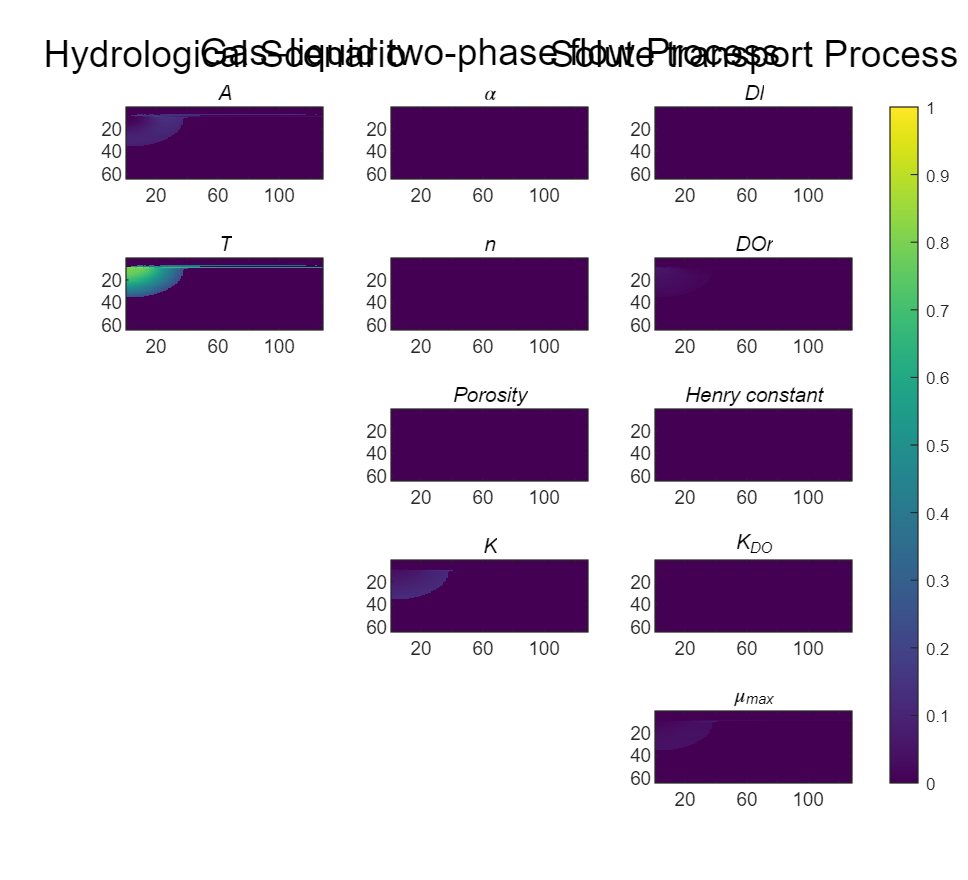

load('Musk_5d.mat')
param = {'A' 'T' '\alpha' 'n' 'Porosity' 'K' 'Dl' 'DOr' 'Henry constant' 'K_{DO}' '\mu_{max}'};
proc = {'Hydrological Scenario', 'Gas–liquid two-phase flow Process', 'Solute transport Process'};

% 一阶
id = [1 4 2 5 8 11 3 6 9 12 15];
f = tiledlayout(5,3);
set(gcf,'position',[100 10 1100 1000])
for i = 1:11
    nexttile(id(i))
    imagesc(SI1(:,:,i).*Musk_av,'CDataMapping','scaled')
    colormap(mymap("viridis"))
    set(gca,'CLim',[0,1])
    if id(i) <=3
        [t,s] = title(proc(id(i)),param(i));
        t.FontSize = 16;s.FontAngle = 'italic';
    else
        title(param(i),'FontAngle','italic');
    end
end
cb = colorbar;
cb.Layout.Tile = 'east';

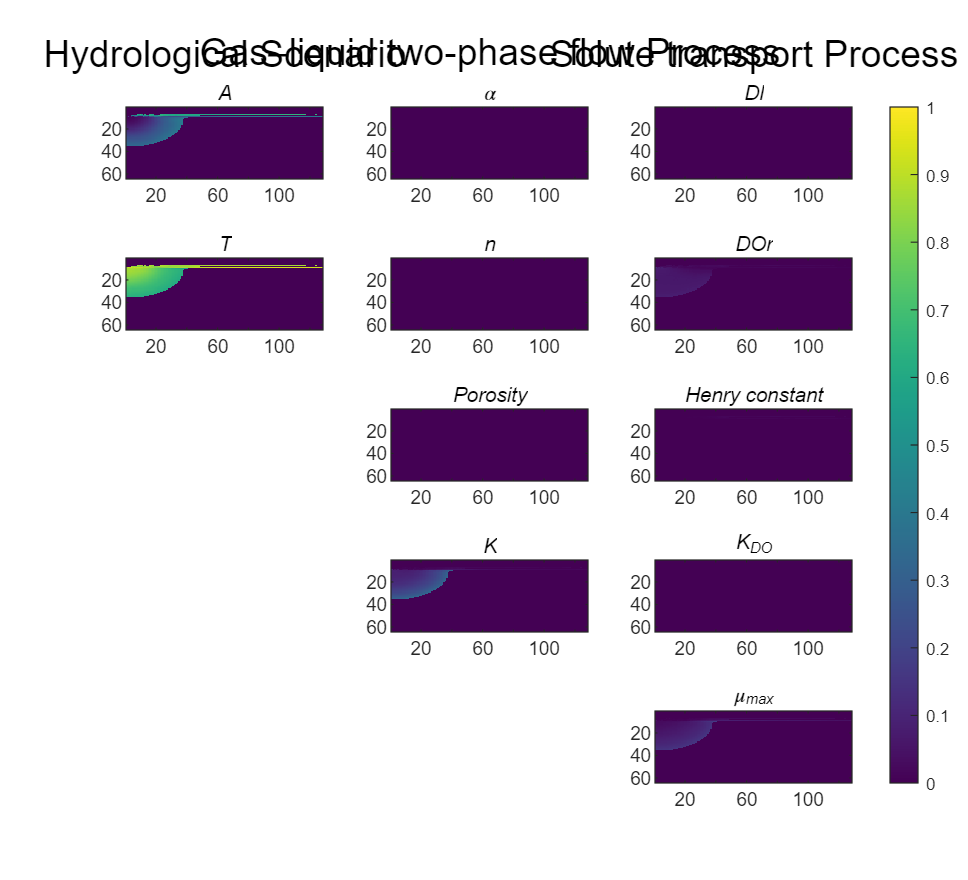


% 总阶
id = [1 4 2 5 8 11 3 6 9 12 15];
f1 = tiledlayout(5,3);
set(gcf,'position',[100 10 1100 1000])
for i = 1:11
    nexttile(id(i))
    imagesc(SIT(:,:,i).*Musk_av,'CDataMapping','scaled')
    colormap(mymap("viridis"))
    set(gca,'CLim',[0,1])
    if id(i) <=3
        [t,s] = title(proc(id(i)),param(i));
        t.FontSize = 16;s.FontAngle = 'italic';
    else
        title(param(i),'FontAngle','italic');
    end
end
cb = colorbar;
cb.Layout.Tile = 'east';

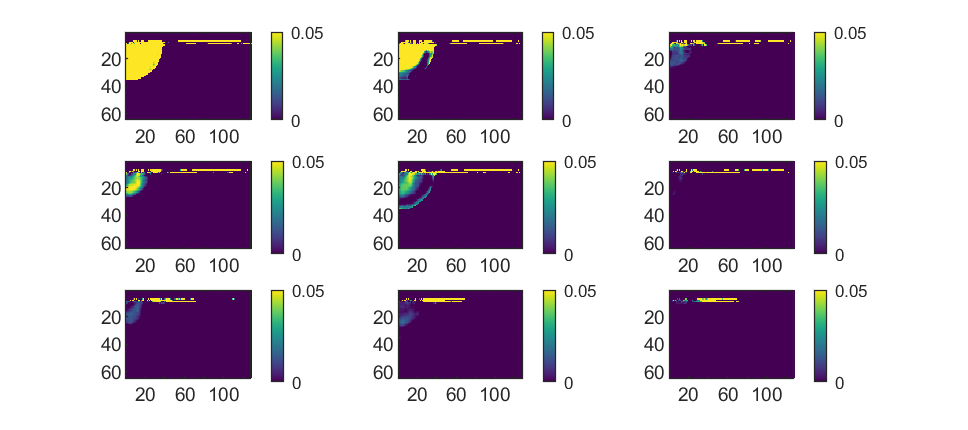


% 收敛情况
f2 = figure;
set(gcf,'position',[150 150 1800 800])
subplot(3,3,1);
for i = 1:(10-1)
    subplot(3,3,i);
    imagesc(squeeze((SI1_D(:,:,8,i)-SI1_D(:,:,8,10))).*Musk_av./SI1(:,:,8),'CDataMapping','scaled')
    colormap(mymap("viridis"))
    set(gca,'CLim',[0,0.05])
    colorbar
end

function [SI1, SIT] = SI_Parameter(Y)
[H,W,~,n] = size(Y);
V_c = var(reshape(Y,[H,W,n*n]),[],3);
Vi_E = var(mean(Y,4),[],3);
V_Ei = var(mean(Y,3),[],4);

SI1= Vi_E./V_c;
SIT = (V_c-V_Ei)./V_c;
end


function X0 = sobolr(N, P) % U [0 1]
S = 1000;
L= 100;
p = sobolset(P, 'Skip', S, 'Leap', L);
p = scramble(p, 'MatousekAffineOwen');
X0 = net(p, N);
end


function Y = soboln(X0) % N 有效区间[-3 3]
Y = icdf('Normal', X0, 0, 1);
end


function Y = sobolln(X0) % LN 有效区间[0,13]
Y = icdf('Normal', X0, 0, 1);
Y = exp(Y);
end